## 1. Generate two sets of 1,000 random numbers that are drawn from the normal distribution (Hint: randn). Create a scatter plot of the first set of numbers against the second set of numbers. Label the two axes as "Condition A" and "Condition B". Show the resulting figure

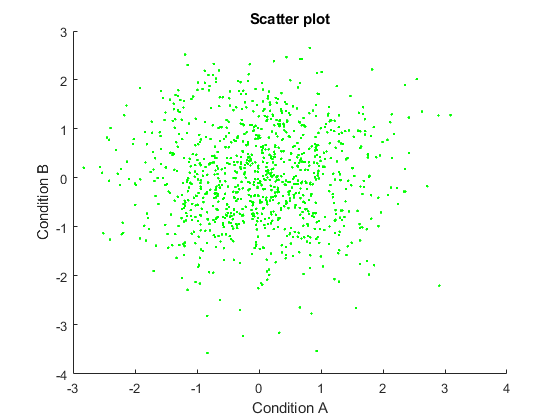

count = 1000;
% randn(1, count) function generates two massives of size 1 * count with
% number elements (normal distribution)
% g. - the scatter will be drawn using: 'g = green, . = dots'
h = scatter(randn(1, count), randn(1, count), 'g.');
xlabel('Condition A');
ylabel('Condition B');
title('Scatter plot');

## 2. The data1 variable in Homework1.mat is a matrix of dimensions 2 x 20. Sum the numbers in each row and then compute the ratio between the two sums (i.e. sum of row 1 divided by sum of row 2). Store the answer in a variable called result and echo the value of this variable to the screen.

% load data from file into file and get value of 'data1' variable
file = matfile('Homework1.mat');
data1 = file.data1;
% calculate sums of 1st and 2nd rows
sum1 = sum(data1(1,:));
sum2 = sum(data1(2,:));
result = sum1 / sum2;
% output the result
fprintf('The ratio between sums of two rows: \n%f / %f = %f', sum1, sum2, result);

The ratio between sums of two rows: 
514.000000 / 1172.000000 = 0.438567

## 3. The timeA, valsA, timeB, valsB variables in Homework1.mat represent time-series data for two signals, A and B. The time points at which A was measured are given in timeA, and the corresponding measurements are given in valsA. (The same goes for B, timeB, and valsB.) Create a figure in which both signals are plotted as lines. Use a red line for A and a green line for B. Label the two axes and add a title and legend to the figure. Show the resulting figure.

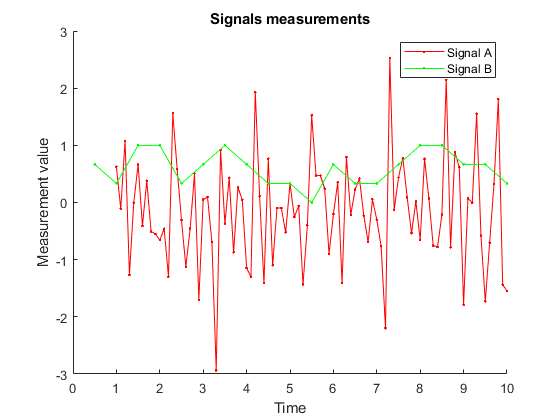

timeA = file.timeA;
valsA = file.valsA;
timeB = file.timeB;
valsB = file.valsB;
figure;
% figures will be addded on a picture
hold on;
%r/g.- means 'r - red/ g - green, . - point markers, - solid line'
h1 = plot(timeA, valsA, 'r.-');
h2 = plot(timeB, valsB, 'g.-');
xlabel('Time');
ylabel('Measurement value');
title('Signals measurements');
% legends
legend([h1 h2],{'Signal A' 'Signal B'});

## 4. Create a variable containing the matrix shown to the right. Then, append a new row to the matrix that consists of all 1s. Then, change the top-right element of the matrix to 0. Finally, extract the last column of the matrix and reshape it to be a row vector. Store this vector in a variable called result and echo the value of this variable to the screen.

% create a matrix with a given values
matrix = [3, -1, 1.5; 2, 0, 0; 1, 1, 1];
% append a row with values of the 1st row
matrix = matrix([1:3,1],:);
% change the value of top-right element (1 row, 3 column) to 0
matrix(1,3) = 0;
% get the last column as a vector and transpose it to a row
row = transpose(matrix(:,3));
disp('Transposed last column:');

Transposed last column:


disp(row);

         0         0    1.0000    1.5000



## 5. Write a function called checkpositive.m that accepts a 2D matrix as input and outputs a row vector. The row vector should contain as many elements as there are rows in the 2D matrix, and each element should indicate whether the corresponding row in the 2D matrix contains all positive numbers (use 0 to indicate no and 1 to indicate yes). The function should also report the results to the command window.

inputMatrix = [4 1 1; -1 0 0; 0 0 0; .1 .2 .1];
output = checkpositive(inputMatrix);

Function output:
Row 1: yes
Row 2: no
Row 3: no
Row 4: yes


disp('Input matrix:');

Input matrix:


disp(inputMatrix);

    4.0000    1.0000    1.0000
   -1.0000         0         0
         0         0         0
    0.1000    0.2000    0.1000



disp('Result (1 - "yes", 0 - "no"):');

Result (1 - "yes", 0 - "no"):


disp(output);

     1
     0
     0
     1



% checkpositive function
% get a matrix of any size as an input (m, n)
% returns a column-matrix of m rows as an output (m, 1)
% with output result for each input row
% The function checks if all values in a row are positive or not
% 1 corresponds to the case that all values are positive
% and 0 - to the opposite
% ----
% initially the output vector is filled by 0 values,
% which may be changed to 1

function output = checkpositive(matrix)
disp('Function output:');
output = zeros(size(matrix,1),1);
    for rowNum = 1:size(matrix, 1)
        if min(matrix(rowNum,:)) > 0
            output(rowNum) = 1;
            fprintf('Row %d: yes\n', rowNum);
        else
            fprintf('Row %d: no\n', rowNum);
        end
    end
end